v = 100;
alpha = pi*70/180;
g = 9.801;
clock = 0.01;
x = 0, h = 0;

x = 0

vx = v*cos(alpha);
vy = v*sin(alpha);
t = (vy/g) * 2;

xs = [];
ys = [];

for tx = 0 : clock : (t/2)+clock
    xs = [xs, x];
    ys = [ys, h];
    x = x + vx * clock;
    vt = vy - g * tx;
    h = ((vy + vt) / 2) * tx;
end
peak = h

peak = 450.4755

for tx = 0 : clock : (t/2)+clock
    xs = [xs, x];
    ys = [ys, h];
    x = x + vx * clock; 
    vt = g * tx;
    h = peak - (vt * tx / 2); 
end
zs = zeros(size(xs));
peak, vx, vy, vt, v_last = sqrt(vt^2 + vx^2)

peak = 450.4755

vx = 34.2020

vy = 93.9693

vt = 93.9916

v_last = 100.0210

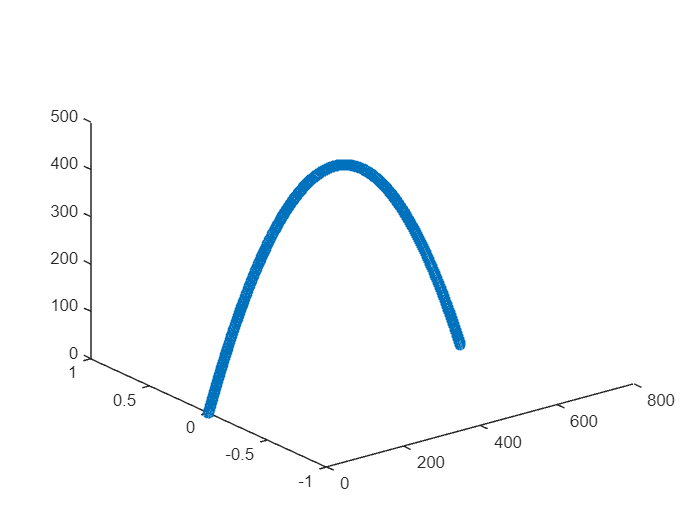

plot3(xs, zs, ys, "o")